# LECTURE WEEK VI. - EXERCISE

# FREQUENCY RESPONSE OF FILTERS & CONVOLUTION USING DTFT/DFT

**Objectives:**

- Compute and visualize the transfer function of an FIR filter using the DFT.

- Relation between DTFT and DFT of the transfer function.

- Implementing convolution using DFTs.

- Speed difference between convolution in the time domain and Fourier domain.

- Linear and circular convolutions.

- Designing the impulse response of an FIR filter by specifying its transfer function in the DFT domain.

## MATLAB Exercise VI.1: DTFT versus DFT Transfer Function

## (Theory exercise VI.1 I)

We consider the LTI system given by the input-output relation (see theory exercise ***VI.1 I***):

***A.***

The DTFT-version of the frequency response $H(e^{j\hat{\omega}})$ is computed as


$$H(e^{j\hat{\omega}}) = \sum_{k=0}^{M} h[k]e^{-j\hat{\omega}k} \quad -\pi \leq \hat{\omega} \leq \pi$$


and already given in theory exercise ***VI.1 I***. Manually sketch the frequency response $H(e^{j\hat{\omega}})$.

You can also use MATLAB to make a function plot, for instance of the magnitude of the DTFT frequency response.

H = @(w) 1 + 2 * exp(-3 * 1i *w);
fplot(@(w) abs(H(w)), [-pi, pi])
axis([-pi pi 0 4]);

***B.***

In practical implementations we use the DFT-version of the frequency response, which is given by


$$H[k] = \sum_{n=0}^{N-1} h[n]e^{-j\frac{2\pi}{N}kn} \quad k = 0,\dots,N-1$$


Manually compute and draw the frquency response $H[k]$ for N=8 and N=256 using the above equation. Compare to the result in part ***A***. Remember how the horizontal axis of the DTFT and DFT are related!

You can also use MATLAB to make this plot, for instance of the magnitude of the DF frequency response.

omega = @(k, N) (k-1) * ((2 * pi) / N);
H     = @(k, N) 1 + 2 * exp(-3 * 1i * k * (2 * pi / N));
N     = 8;
k     = 1:N;
stem(omega(k, N), abs(H(k-1, N)))
axis([0 2 * pi 0 4]);

***C.***

Now use MATLAB to compute and plot the frequency response $H[k]$. First create the impulse response in a vector `hh` of length `N=8`. Then use the function `fft` to compute the frequency response in the vector `HH`. 

***Answer:***

N     = 8;
k     = 1:N;
hh    = [1 0 0 2];
hh(N) = 0;
HH = fft(hh);

Make two plots (or stem plot), one for magnitude spectrum and one for the phase spectrum. Use digital frequencies - running from 0 to $2\pi$ - rather than DFT coefficient indices on the horizontal axis. Compare to the result in part ***C***. (They should be same!).

stem(omega(k, N), abs(HH));
axis([0 2 * pi 0 4]);

***D.***

Repeat part ***D*** for **N=256** and **N=512**, i.e. place the impulse response in a vector of length 256 and 512, respectively, and compute the DFT of these vectors. 

***Answer:***

Compare to the result in part ***C*** and ***D***. What is your conclusion concerning the DFT length and the ability to resolve the behavior of the filter for different frequencies? For which value of N does the DFT-version of the frequency response best resemble the DTFT-version computed in part ***A***?

***Answer:***

## MATLAB Excercise VI.2: Convolution Using DFT

The frequency response of a filter is often used to efficiently implement a convolution. The following relationship holds:


$$y[n] = \underbrace{h[n] * x[n]}_{
    \text{direct convolution}
}
\quad
\Leftrightarrow
\quad
Y[k] = \underbrace{H[k].X[k]}_{\text{product of DFT transforms}}$$


***A.***

Consider the LTI system with the following input-output relation


$$y[n] = 3x[n] - x[n-1] + 2x[n-2] + x[n-3] - 2x[n-4]$$


and the input signal

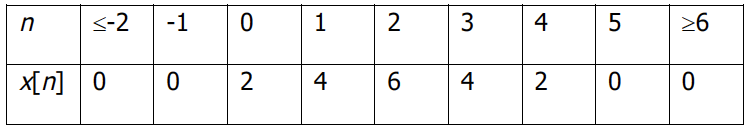

Compute the output $y[n]$ manually with MATLAB using normal (direct) convolution.

***Answer:***

hh     = [3 -1 2 1 -2];
hh(32) = 0;
xx     = [2 4 6 4 2];
xx(32) = 0;
yyt    = conv(hh, xx);
stem(yyt);

***B.***

Place the impulse response $h[n]$ in a vector `hh` of length 32. Similarly, place the input signal $x[n]$ in a vector `xx` of length 32. Compute the DFT of $h[n]$ and $x[n]$ using MATLABs `fft()` function, multiply the two DFT results, and compute the inverse DFT using the `ifft()` function. Make a stem plot of the result and compare to the result in part ***A***. 

***Answer:***

HH  = fft(hh);
XX  = fft(xx);
YY  = HH .* XX;
yyf = ifft(YY);
stem(yyf);

Are there differences between the results of time-domain convolution and convolution in the Fourier domain?

***Answer:***

***C.***

Carry out the following convolutions in the Fourier domain, and compare the resulting signals $y[n]$ with the results that you obtain by time-domain convolutions. Use a suitable value of *N*.

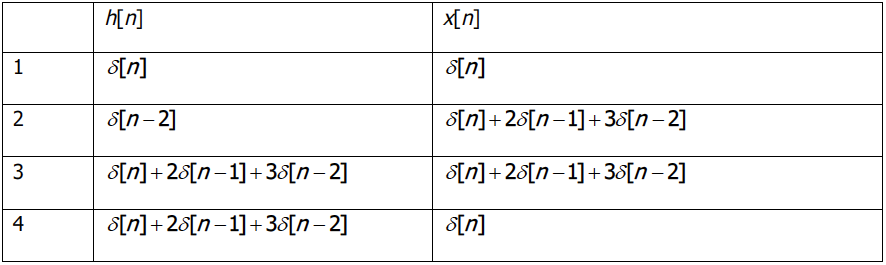

***Answer:***

## MATLAB Exercise VI.3: Exercise I.3 Revisited

In MATLAB Exercise I.3 we have applied an FIR filter to the degraded speech signal '`data/welkomdegraded.wav`'. After applying the FIR filter with impulse response $h_2[n] = \delta[n] + \delta[n-1] + \delta[n-2]$ the quality of the signal improved a lot, and in particular the high pitched tone had disappeared.

Compare and plot the spectrum of the degraded speech signal and the frequency response of the FIR filter, and give an explanation why we were successsful in removing the high pitched tone by filtering the signal. It may be helpful to make the plots using a vertical log-scale, which can be achieved by the Figure menu option: Edit -> Axis Properties...

***Answer:***

[xx, Fs] = audioread('data/welkomdegraded.wav');
sound(xx, Fs);
pause(4);
h        = [1 1 1];
yy       = FIR3(xx, h);
sound(yy, Fs);

subplot(2, 1, 1);
stem(abs(XX));
set(gca, 'YScale', 'log');
title('Spectrum of welkomdegraded.wav (log scale)');

hh(length(xx)) = 0;
HH = fft(hh);
subplot(2, 1, 2);
stem(abs(HH));
set(gca, 'YScale', 'log');
title('Spectrum of filter [1 1 1] (log scale)');

What would have been the ideal frequency response of the FIR filter to remove the high pitched tone but leaving the desired speech unaffected?

***Answer:***